# Helpers for `run_draw`

`Run the first three sections of this live script to prepare the model, then run the last section in the Command Window.`

imgs_3 = img_load("data/extracted_images/3");
imgs_4 = img_load("data/extracted_images/4");
imgs_6 = img_load("data/extracted_images/6");
size(imgs_3)

ans =        10909        2025


size(imgs_4)

ans =         7396        2025


imgs = [imgs_3(1:3000, :); imgs_4(1:3000, :); imgs_6(1:3000, :)];


labels = [repmat("3", 1, 3000) repmat("4", 1, 3000) repmat("6", 1, 3000)]; % WARNING: Very advanced algorithm. Move over Google.

model = train_model(imgs, labels, 150);

load model.mat;

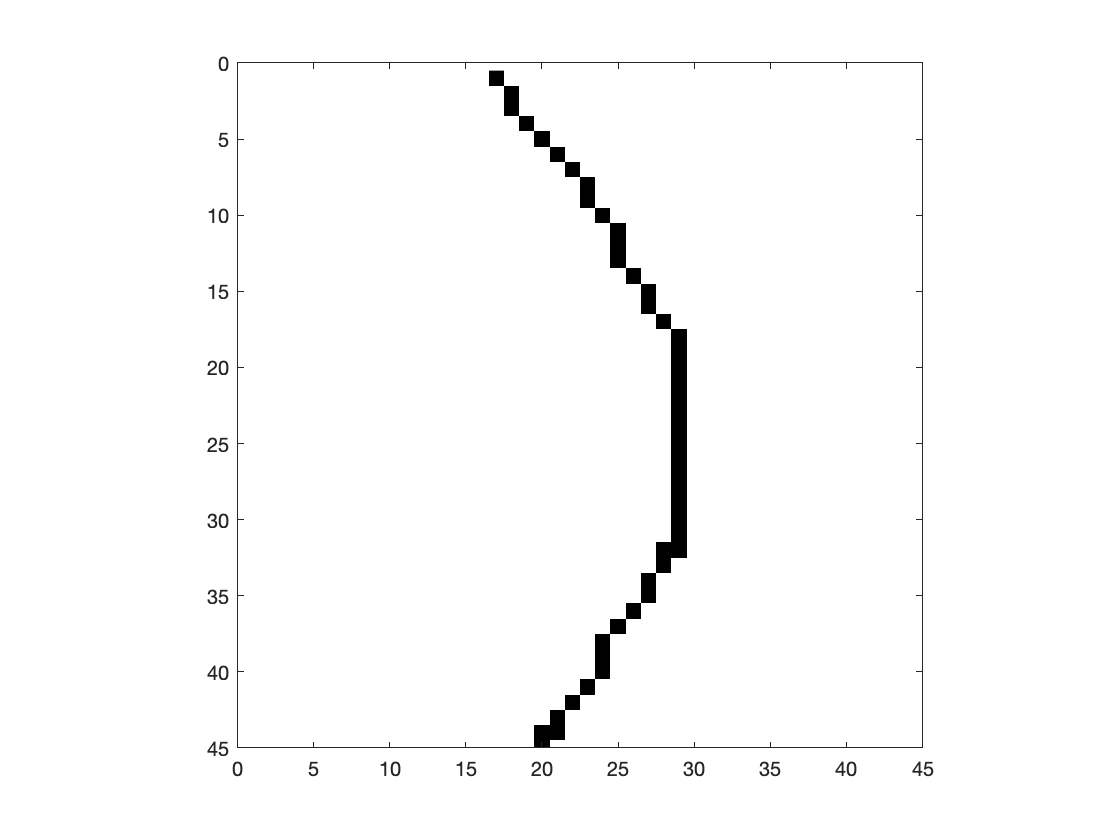

imagesc(reshape(model.training_imgs(3725, :), [45 45])); axis equal; colormap("gray"); xlim([0 45]); ylim([0 45])

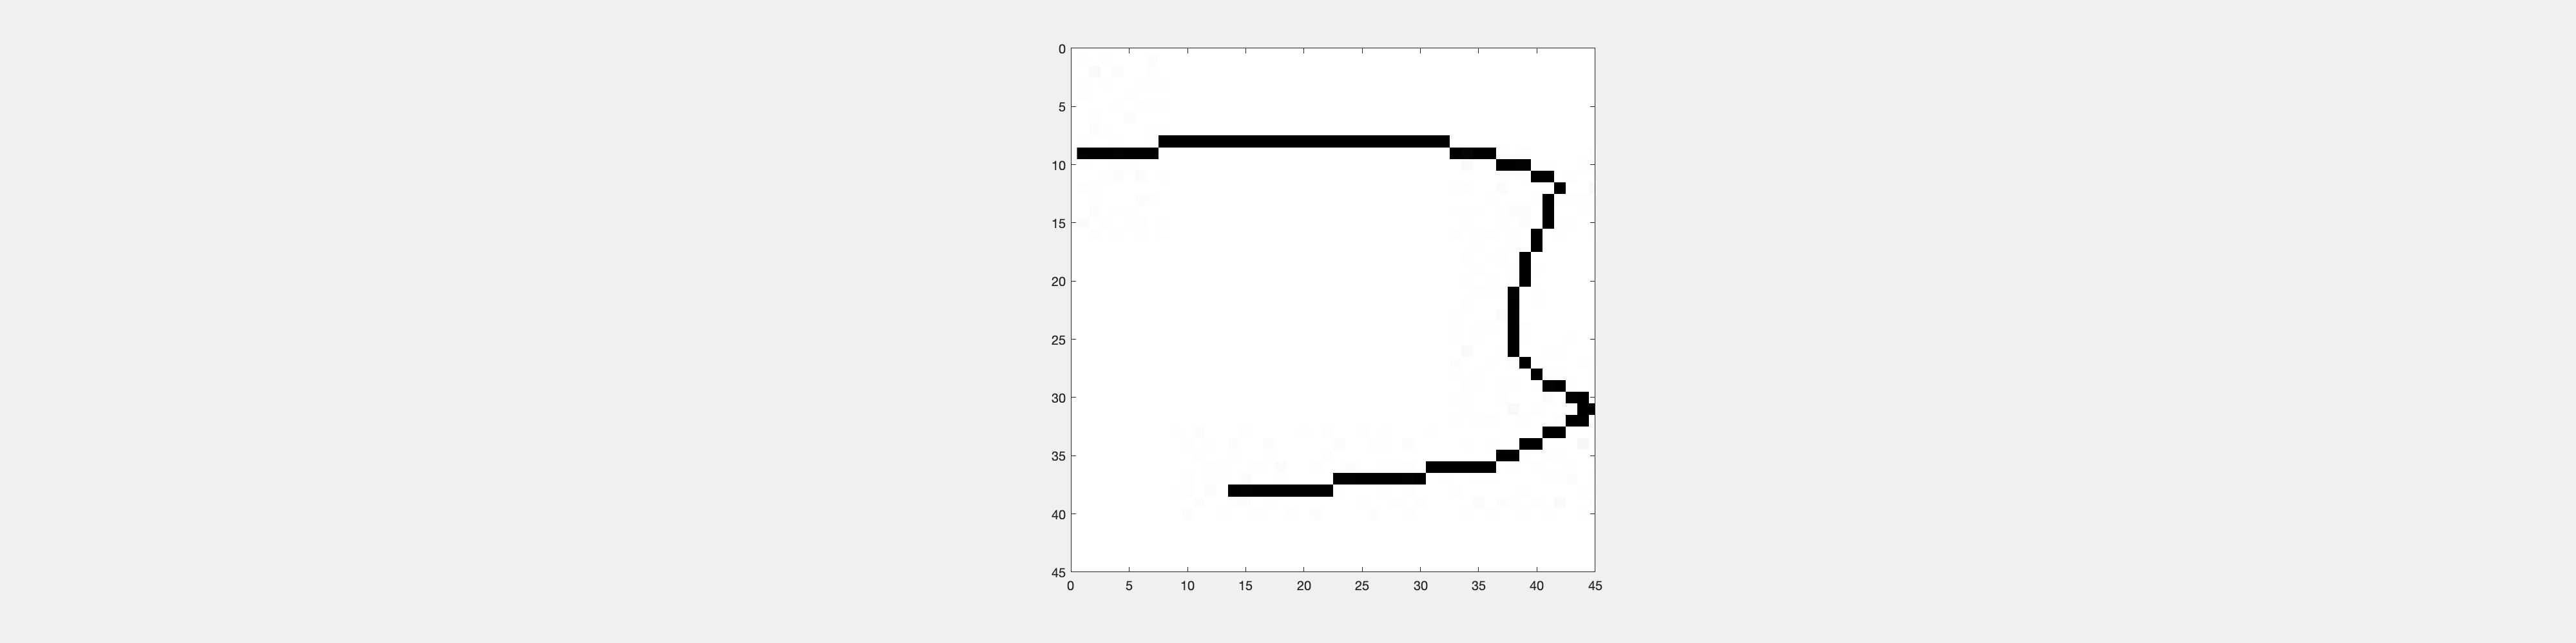

% This doesn't actually work in a live script, but run the rest of the live
% script to prep the model then run this in the Command Window.
main(model)